# Example 1: executing a simulation

### This assumes the database and default data has been set up

## 1. add directory contents to exec path

% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), '\');
idx = find(strcmp(file_path, 'uavtestbed'));
root_directory = strjoin(file_path(1:idx), '\')

root_directory = 'G:\Dropbox\NASA\uavtestbed'

% switch to the root directory
cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% load the api
api = jsondecode(fileread('sql/api.json'));

## 2. Retrieve UAV and preface info from db

- flight num / flight id

- last timestamp

- stop codes and group ids

% the database connection
conn = db_connect('nasadb');


% check out what UAVs are in the db
uav_tb = select(conn, 'select asset_tb.serial_number, asset_tb.common_name, uav_tb.* from uav_tb join asset_tb on asset_tb.id = uav_tb.id;')

uav_tb = 2×15 table
    serial_number       common_name       id    airframe_id    battery_id    m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    max_flight_time    dynamics_srate
    _____________    _________________    __    ___________    __________    _____    _____    _____    _____    _____    _____    _____    _____    _______________    ______________

     {'B27EA8'}      {'default'      }    11         1              2         10        9        8     

% load the UAV 
% note, the default UAV is not supported any more and some functionality
% below will be skipped if using the default uav (recommended to use the
% tarot)

%%%%% this is commented out until the database has been refactored
uav = load_uav(conn, uav_tb.serial_number{2});
%%%%% use this instead
% uav = load('params/uav.mat').uav;
uav

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [8×1 struct]
    max_flight_time: 14.9000
                 id: 22
     dynamics_srate: 0.0250
               mass: 10.6600


### Load the stop_code_tb and group_tb

% to match stop codes with the simulation
% new stop codes for your specific experiment can be created
stop_code_tb = select(conn, "select * from stop_code_tb;")

stop_code_tb = 6×2 table
    id           description        
    __    __________________________

    1     {'low soc'               }
    2     {'low voltage'           }
    3     {'max position error'    }
    4     {'arrival success'       }
    5     {'average position error'}
    6     {'low soh (battery)'     }


% for organizing multiple executions
group_id_tb = select(conn, "select * from group_tb")

group_id_tb = 1×2 table
    id        info    
    __    ____________

    1     {'examaple'}


group_id = group_id_tb.id(1);

### Look at the flight summary table and get the last timestamp and flight_id

- since these are simulations, the simulation time will grow beyond real time so we cannot just use " datestr(now) " as the start time

- The start time is important because the telemetry data is indexed via timestamp

- the start and stop timestamps in the flight_summary_tb are used to access the flight telemetry data for that flight

- the flight_id refers to the id field of flight_summary_tb

% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from flight_summary_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second')

dt_start = datetime
   24-Aug-2021 21:42:11


% get the flight_id (the unique id in the data table)
flight_id = table2array(select(conn, 'select id from flight_summary_tb order by id desc limit 1;')) + 1


flight_id =

  0×1 empty double column vector



if isempty(flight_id)
    flight_id = 1;
end

% the flight number of the selected uav (i.e. how many flights it has gone
% previously + 1 for the upcomming flight)
flight_num = table2array(select(conn, sprintf('select flight_num from flight_summary_tb where uav_id = %d order by dt_start desc limit 1;', uav.id))) + 1;
if isempty(flight_num)
    flight_num = 1;
end

% close the connection and clear the table (the data is in the uav struct now)
conn.close();
clear('uav_tb', 'conn');

## 3. Load the trajectory

% load the trajectory information
% there are 37 different trajectories, this function will return one that
% is closest to the second parameter in the function (uav.max_flight_time)
% with valid numbers (minutes) between 6 and 22. 
%trajectory = get_trajectory('trajectories/trajectories.csv', uav.max_flight_time, desired_velocity);

trajectory_tb = readtable('trajectories/trajectories_exported.csv');
trajectory_tb = trajectory_tb(trajectory_tb.path_time < uav.max_flight_time, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')

trajectory_tb = 8×13 table
    id    path_distance    path_time    risk_factor         start            destination             x_waypoints               y_waypoints                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           

trajectory = get_trajectory(trajectory_tb, 1)

trajectory = struct with fields:
               id: 7
    path_distance: 656.5600
        path_time: 8.4200
      risk_factor: 0.0100
            start: [50 25]
      destination: [350 350]
     x_ref_points: [505×2 double]
     y_ref_points: [505×2 double]
      sample_time: 1
           reward: 1
              map: 'map1'
        waypoints: [2×2 double]
             path: [26×2 double]


### Plot the trajectory

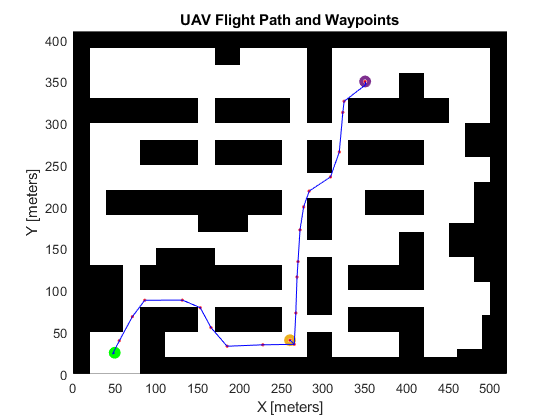

f2 = figure(2); clf;
map = load(sprintf('trajectories/%s.mat', trajectory.map)).(sprintf('%s', trajectory.map));
hold on;
show(map);
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(trajectory.path-1)
    plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")

clear map;

## 4. Setup simulation params

% stop measure on the simulation, in general it should stop before this
sim_params.max_sim_time = 4000;

% performance thresholds %%%% max_pos_err calculation is incorrect (does
% not account for time offset, needs updated)
sim_params.perf_param_thresh.max_pos_err  = 10; % this is check in the simulation
sim_params.perf_param_thresh.min_soc      = .2; % this is check in the simulation
sim_params.perf_param_thresh.min_v        = uav.battery.EOD * 1.075; % this is checked in the simulation
sim_params.perf_param_thresh.min_soh_batt = uav.battery.Q * .6; % this is checked after
sim_params.perf_param_thresh.avg_pos_err  = 2.8; % this is checked after
sim_params.perf_param_thresh.pos_err_var  = 10; % check this 

% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;
sim_params.initial_conditions  = load('params/IC_HoverAt10fttarot.mat').IC;

sim_params.battery_estimator   = load('estimation/batteryestimator').batteryestimator;
sim_params.battery_estimator.Qinit = uav.battery.Q;
if uav.battery.v0 < 4.3
    sim_params.battery_estimator.soc_ocv = interp1([sim_params.battery_estimator.soc_ocv(1) sim_params.battery_estimator.soc_ocv(end)], [3.04 4.2], sim_params.battery_estimator.soc_ocv);
end

sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;

sim_params.initial_conditions.X = trajectory.start(1);
sim_params.initial_conditions.Y = trajectory.start(2);

## 5. Load process data

- environment (wind)

- degradation (battery, motors)

### this will get a single process


process_type = 'degradation';
subtype1 = 'battery';
subtype2 = 'capacitance';
description = 'continuous';
% returns all process data
%select(conn, eval(api.matlab.process.LOAD_PROCESS))
% use .parameters to get only the degradation parameters
p = select(conn, eval(api.matlab.process.LOAD_PROCESS)).parameters

p = 1×1 cell array
    {'{"q_coef": [-4.89511264247582e-08, 2.57136010019803e-05, 21.7779510188925]}'}



p =

  1×0 empty cell array



### this will get all processes of a given type (degradation or environment)

process_type = 'degradation';
select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))   

ans = 13×9 table
    id         type           subtype1             subtype2            id_1    type_id             description                                  source                                                                                                                                                       parameters                                                                                                                             
    __    _______________    ___________    _______________________    ____    _______    _____________________________    _________________________________________________    _________________________________________________________________________

process_type = 'environment';
select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))  

ans = 1×9 table
    id         type          subtype1    subtype2    id_1    type_id                                    description                                                  source                                        parameters                       
    __    _______________    ________    ________    ____    _______    ____________________________________________________________________________    ________________________________    ________________________________________________________

    4     {'environment'}    {'wind'}    {'gust'}     4         4       {'simulated wind gusts through direct application of force to the airframe'}    {'generated by experimentation'}   

## 5. Simulate

tic
if strcmp(uav.uav.common_name, 'tarot t18 uav')
    sim('simulink/uav_simulation_tarot.slx');
else 
    sim('simulink/uav_simulation.slx');
end

Cannot start a new command line simulation while a simulation has started for the same model.

toc

#### calculate dt_stop

dt_stop = dt_start + minutes(time.Data(end, 1))

## 5a. check stop codes and system performance parameter thresholds

- stop codes 1-4 are checked in simulation

stop_code_tb
stop_code = max(find(any(stop_codes.Data(:,:))))
string(stop_code_tb.description(stop_code_tb.id==stop_code))

#### check the average position error threshold

if mean(errors.euclidean_pos_err.Data) > sim_params.perf_param_thresh.avg_pos_err
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'average position error'))
end

#### check the minimum state of health for the battery threshold (battery.Q aka q_deg)

if  uav.battery.Q < sim_params.perf_param_thresh.min_soh_batt
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'low soh (battery)'))
end


## 6. Update component degradation parameters

- battery

if strcmp(string(uav.uav.common_name), "tarot t18 uav")
    avg_current = abs(mean(battery.battery_true.i.Data(:)))
    flight_time = time.Data(end)/60 % time.Data is already in minutes, time.time however is in seconds
    amp_hours = avg_current * flight_time;
    uav.battery.amp_hours = uav.battery.amp_hours + amp_hours;
    uav.battery.amp_hours
    uav.battery.age = uav.battery.amp_hours / uav.battery.lifetime_amp_hrs;
    uav.battery.age
    uav.battery.Q = polyval(uav.battery.q_coef, uav.battery.amp_hours);
    uav.battery.Q
    uav.battery.R0 = polyval(uav.battery.r_coef, uav.battery.amp_hours);
    uav.battery.R0

avg_current = 63.0187

flight_time = 0.2483

ans = 15.6496

ans = 0.0012

ans = 21.7783

ans = 0.0011

- motors

    for i = 1:length(uav.motors)
        uav.motors(i).age = uav.motors(i).age + motors.(sprintf('m%d',i)).current.Data(end)*flight_time;
        uav.motors(i).Req = polyval(uav.motors(i).r_coef, uav.motors(i).age);
    end

var_names = 1×30 string array
    "id"    "stop_code"    "z_start"    "z_end"    "v_start"    "v_end"    "m1_avg_current"    "m2_avg_current"    "m3_avg_current"    "m4_avg_current"    "m5_avg_current"    "m6_avg_current"    "m7_avg_current"    "m8_avg_current"    "avg_pos_err"    "max_pos_err"    "std_pos_err"    "avg_ctrl_err"    "max_ctrl_err"    "std_ctrl_err"    "distance"    "flight_time"    "avg_current"    "amp_hours"    "dt_start"    "dt_stop"    "trajectory_id"    "uav_id"    "flight_num"    "group_id"


    clear('avg_current', 'flight_time', 'amp_hours');
end

flight_summary_tb = 1×29 table
    stop_code    z_start     z_end     v_start    v_end     m1_avg_current    m2_avg_current    m3_avg_current    m4_avg_current    m5_avg_current    m6_avg_current    m7_avg_current    m8_avg_current    avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours          dt_start                dt_stop           trajectory_id    uav_id    flight_num    group_id
    _________

## 7. Insert summary data into the db

% the database connection
conn = db_connect('nasadb');

% get the variable names, but note "id" isn't used
var_names = get_column_names(conn, 'flight_summary_tb')
flight_summary_tb = table(max(find(any(stop_codes.Data(:,:)))), ...
                          battery.battery_true.z.Data(1), ...
                          battery.battery_true.z.Data(end), ...
                          battery.battery_true.v.Data(1), ...
                          battery.battery_true.v.Data(end), ...
                          mean(motors.m1.current), ...
                          mean(motors.m2.current), ...

var_names = 1×14 string array
    "id"    "flight_id"    "q_deg"    "q_var"    "q_slope"    "q_intercept"    "r_deg"    "r_var"    "r_slope"    "r_intercept"    "m_deg"    "m_var"    "m_slope"    "m_intercept"


                          mean(motors.m3.current), ...
                          mean(motors.m4.current), ...
                          mean(motors.m5.current), ...

var_names = 1×4 cell array
    {'flight_id'}    {'q_deg'}    {'r_deg'}    {'m_deg'}


                          mean(motors.m6.current), ...
                          mean(motors.m7.current), ...
                          mean(motors.m8.current), ...
                          mean(errors.euclidean_pos_err), ...
                          max(errors.euclidean_pos_err), ...

flight_degradation_tb = 1×4 table
    flight_id    q_deg    r_deg     m_deg
    _________    _____    ______    _____

        4         22      0.0011    0.27 


                          std(errors.euclidean_pos_err), ...
                          mean(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          max(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          std(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          round(calculatedistance([position.true.Data(:,1) position.true.Data(:,2)]), 4), ...
                          time.Time(end)/60, ...
                          mean(battery.battery_true.i.Data), ...
                          mean(battery.battery_true.i.Data)*time.Time(end)/60/60, ...
                          dt_start, ...
                          dt_start + minutes(time.Time(end)/60), ...
                          trajectory.id, ...
                          uav.id, ...
                          flight_num, ...
                          group_id, ...

ans = 40.0034

                          'VariableNames',  cellstr(var_names(1,2:end)))
% write the data to the database
sqlwrite(conn, 'flight_summary_tb', flight_summary_tb);

ans = 40

conn.commit();
conn.close();
clear conn;

ans = 40.0034

## 8. Get the degradation data and insert it

% the database connection
conn = db_connect('nasadb');

% get var names

battery_tt = 895×9 timetable
     Time     battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var
    ______    ______________    ______________    ______________    ______________    _____________    _____________    _____________    _________________    _________________

    0 sec           22.2                 1            0.0011            65.335             22.2                 1            0.0011                 0                 0.003    
    1 sec         22.123            0.9992            0.0011        

var_names = get_column_names(conn, 'flight_degradation_tb')

#### flight_id refers to the id field of the flight_summary_tb. This is pulled from the beginning

#### also, on this flight we are only inserting 4 parameters, the 4 required parameters to use this table

var_names = {'flight_id' 'q_deg' 'r_deg' 'm_deg'}
flight_degradation_tb = table(flight_id, ...
                              uav.battery.Q, ...
                              uav.battery.R0, ...
                              uav.motors(2).Req, ...
                              'VariableNames', var_names)

errors_tt = 895×5 timetable
     Time     euclidean_pos_err    x_pos_err    y_pos_err    x_ctrl_err    y_ctrl_err
    ______    _________________    _________    _________    __________    __________

    0 sec         0.063246             0.02         0.06     -0.073767      -0.24339 
    1 sec           0.9525         -0.38384     -0.87173       0.49051       0.77836 
    2 sec           1.7122          -0.6778      -1.5724        0.6601        1.6031 
    3 sec           1.8128          -0.7015      -1.6715       0.66003        1.6367 
    4 sec           1.5848         -0.60587      -1.4644       0.63599        1.5343 
    5 sec           1.4942         -0.75393      -1.2901       

clear('var_names');
% connect to the database
conn = db_connect('nasadb');
% write the data to the database
sqlwrite(conn, 'flight_degradation_tb', flight_degradation_tb);
conn.commit();

environment_tt = 895×3 timetable
     Time     wind_gust_x    wind_gust_y    wind_gust_z
    ______    ___________    ___________    ___________

    0 sec        3.1623          2.0197       4.0475   
    1 sec        1.9289          3.3036       3.2865   
    2 sec        3.4731         0.99865       2.5062   
    3 sec        1.0423           3.499       2.8972   
    4 sec      -0.44385          3.3341        1.415   
    5 sec          2.38          1.3944       4.7987   
    6 sec         2.421          1.7033       2.4835   
    7 sec        2.6542          5.4761       4.9414   
    8 sec       -0.4786          3.2512       2.7734   
    9 sec        1.8943          1.0478     

conn.close();
clear conn;

motors_tt = 895×24 timetable
     Time     m1_rpm    m1_torque    m1_current    m2_rpm    m2_torque    m2_current    m3_rpm    m3_torque    m3_current    m4_rpm    m4_torque    m4_current    m5_rpm    m5_torque    m5_current    m6_rpm    m6_torque    m6_current    m7_rpm    m7_torque    m7_current    m8_rpm    m8_torque    m8_current
    ______    ______    _________    __________    ______    _________    __________    ______    

## 9. Get the telemetry data

#### There are multiple different sample rates

- The battery is sampled at 1hz

t_batt = battery.battery_true.v.Time;
1/mean(diff(t_batt))

- airframe dynamics at 40hz

t_dynamics = errors.ctrl_err.x_error.Time;
1/mean(diff(t_dynamics))

- Other variables step with the simulation

- That small difference needs accounted for!

t_sim = time.Time;
1/mean(diff(t_sim))
clear('t_batt', 't_dynamics', 't_sim');

### Battery data

sample_rate = 1;

position_tt = 895×6 timetable
     Time     x_pos_gps    y_pos_gps    z_pos_gps    x_pos_true    y_pos_true    z_pos_true
    ______    _________    _________    _________    __________    __________    __________

    0 sec      50.054       25.183       2.7741            50            25             3  
    1 sec      50.019       25.162       3.1821        50.126        25.068        3.1471  
    2 sec       50.38       25.337       3.3861        50.362        25.368        3.3993  
    3 sec       50.93       26.353       3.6009        50.888        26.318         3.566  
    4 sec      51.504       27.566       3.7374        51.534        27.636        3.6541  
  


battery_tt = sync_telemetry_data(battery, sample_rate, time.Time(:))

### Errors data

errors_tt = sync_telemetry_data(errors, sample_rate, time.Time(:));
errors_tt.Properties.VariableNames{'pos_err_x_pos_err'} = 'x_pos_err';
errors_tt.Properties.VariableNames{'pos_err_y_pos_err'} = 'y_pos_err';
errors_tt.Properties.VariableNames{'ctrl_err_x_error'}  = 'x_ctrl_err';
errors_tt.Properties.VariableNames{'ctrl_err_y_error'}  = 'y_ctrl_err';
errors_tt

### Environment data

environment_tt = sync_telemetry_data(environment, sample_rate, time.Time(:));

velocity_tt = 895×6 timetable
     Time     x_vel_gps    y_vel_gps    z_vel_gps     x_vel_true    y_vel_true    z_vel_true
    ______    _________    _________    __________    __________    __________    __________

    0 sec     0.0043109    0.0015938    -0.0065384           0              0             0 
    1 sec       0.21284      0.10028       0.24307     0.21299       0.099372       0.25089 
    2 sec       0.32908      0.67553       0.22792     0.32611        0.67029       0.22891 
    3 sec       0.70634       1.1789       0.10977     0.70999         1.1772       0.11235 
    4 sec       0.55431        1.408      0.069401     0.55779         1.4103      0.064

environment_tt.Properties.VariableNames{'wind_gust-1'}  = 'wind_gust_x';
environment_tt.Properties.VariableNames{'wind_gust-2'}  = 'wind_gust_y';
environment_tt.Properties.VariableNames{'wind_gust-3'}  = 'wind_gust_z';
environment_tt

### Motor data

motors_tt = sync_telemetry_data(motors, sample_rate, time.Time(:))

flight_telemetry_tb = 895×53 timetable
      dt      battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m2_rpm    m2_torque    m2_current    m3_rpm    m3_torque    m3_current    m4_rpm    m4_torque    m4_current    m5_rpm    m5_torque    m5_current    m6_rpm    m6_torque    m6_current<

### Position data

position_tt = sync_telemetry_data(position, sample_rate, time.Time(:));
position_tt.Properties.VariableNames{'gps-1'}  = 'x_pos_gps';
position_tt.Properties.VariableNames{'gps-2'}  = 'y_pos_gps';
position_tt.Properties.VariableNames{'gps-3'}  = 'z_pos_gps';

flight_telemetry_tb = 895×53 timetable
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m2_rpm    m2_torque    m2_current    m3_rpm    m3_torque    m3_current    m4_rpm    m4_torque    m4_current    m5_rpm    m5_torque    m5_current    m6_rpm    m6_torque    <s

position_tt.Properties.VariableNames{'true-1'}  = 'x_pos_true';
position_tt.Properties.VariableNames{'true-2'}  = 'y_pos_true';
position_tt.Properties.VariableNames{'true-3'}  = 'z_pos_true';
position_tt

### Velocity data

velocity_tt = sync_telemetry_data(velocity, sample_rate, time.Time(:));
velocity_tt.Properties.VariableNames{'gps-1'}  = 'x_vel_gps';
velocity_tt.Properties.VariableNames{'gps-2'}  = 'y_vel_gps';
velocity_tt.Properties.VariableNames{'gps-3'}  = 'z_vel_gps';
velocity_tt.Properties.VariableNames{'true-1'}  = 'x_vel_true';
velocity_tt.Properties.VariableNames{'true-2'}  = 'y_vel_true';
velocity_tt.Properties.VariableNames{'true-3'}  = 'z_vel_true';
velocity_tt

### **Merge the timetables**

flight_telemetry_tb = [battery_tt environment_tt motors_tt errors_tt position_tt velocity_tt];
clear('battery_tt', 'environment_tt', 'motors_tt', 'errors_tt', 'position_tt', 'velocity_tt');
flight_telemetry_tb.Properties.DimensionNames{1} = 'dt';
flight_telemetry_tb

### Convert the time vector duration to a datetime

dt_start.Format = 'MM-dd-uuuu HH:mm:ss.SSS';


idx_v =

  0×1 empty double column vector



dt_stop.Format = 'MM-dd-uuuu HH:mm:ss.SSS';


idx_z =

  0×1 empty double column vector



time_vec = datetime([dt_start: seconds(1/sample_rate) : dt_stop]');


idx_i =

  0×1 empty double column vector



flight_telemetry_tb.dt = time_vec

### Make sure there are no required missing values

- this could typically happen with battery data since it is sampled at a lower frequency than other telemetry data

missing_v = sum(ismissing(flight_telemetry_tb.battery_true_v));
missing_z = sum(ismissing(flight_telemetry_tb.battery_true_z));
missing_i = sum(ismissing(flight_telemetry_tb.battery_true_i));
x = 1:1:20;
vals_v = flight_telemetry_tb.battery_true_v(end-20-missing_v+1:end-missing_v);
vals_z = flight_telemetry_tb.battery_true_z(end-20-missing_z+1:end-missing_z);
vals_i = flight_telemetry_tb.battery_true_i(end-20-missing_i+1:end-missing_i);

flight_telemetry_tb = 895×54 table
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m2_rpm    m2_torque    m2_current    m3_rpm    m3_torque    m3_current    m4_rpm    m4_torque    m4_current    m5_rpm    m5_torque    m5_current    m6_rpm    m6_torque    

poly_v = polyfit(x, vals_v, 1);
poly_z = polyfit(x, vals_z, 1);
poly_i = polyfit(x, vals_i, 1);
missing_vals_v = zeros(1, missing_v);
missing_vals_z = zeros(1, missing_z);
missing_vals_i = zeros(1, missing_i);
for i = 1:missing_v
    missing_vals_v(1,i) = polyval(poly_v, 20+i);
    missing_vals_z(1,i) = polyval(poly_z, 20+i);
    missing_vals_i(1,i) = polyval(poly_i, 20+i);
end

idx_v = find(ismissing(flight_telemetry_tb.battery_true_v))
idx_z = find(ismissing(flight_telemetry_tb.battery_true_z))
idx_i = find(ismissing(flight_telemetry_tb.battery_true_i))

for i = 1:length(idx_z)
    flight_telemetry_tb.battery_true_v(idx_z(i)) = polyval(poly_v, 20+i);
    flight_telemetry_tb.battery_true_z(idx_z(i)) = polyval(poly_z, 20+i);
    flight_telemetry_tb.battery_true_i(idx_z(i)) = polyval(poly_i, 20+i);
end
clear('missing_v', 'missing_z', 'missing_i', 'x', 'vals_v', 'vals_z', 'vals_i', 'poly_v', 'poly_z', 'poly_i', 'missing_vals_v', 'missing_vals_z', 'missing_vals_i', 'idx_v', 'idx_z', 'idx_i', 'dt_start', 'dt_stop', 'time_vec');
flight_telemetry_tb = timetable2table(flight_telemetry_tb)

### Insert the telemetry data into the database

- NOTE - there is an active question on matlab forum regarding miliseconds here [https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types](https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types) 

- currently the telemetry data is sampled at 1hz due to this

% connect to the database
conn = db_connect('nasadb');
% write the data to the database
sqlwrite(conn, 'flight_telemetry_tb', flight_telemetry_tb);
conn.commit();
conn.close();
clear conn;

https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types#comment_1700909